# AER1216 Project - Part 2 - Multi-Rotor Drone Development

## Group Members

David Rolko

Farhan Wadia

Shahzeb Mahmood

close all
clear all
clc

## Flight Range

% Parameters
m = 0.420; % kg
g = 9.81; % N/kg
C_D  = 0.97;
S = 0.01; % m^2
rho = 1.225; % kg/m^3

% APC 8x6 SF Properties
% https://m-selig.ae.illinois.edu/props/volume-1/data/apcsf_8x6_static_2783rd.txt
diam = 8*0.0254; % m

num_cells = 3;
battery_life = 1500; % mA-hr
battery_voltage = 3.7; % V, assumed from propulsion lecture slide 53

W = m*g; % N

P = sqrt(W^3 / (2*rho*(4*pi/4)*(diam)^2)); % W

E_b = num_cells * battery_voltage * (battery_life/1000) * 3600; % J

eta_m = 0.75;
eta_e = 0.85;

% Find max range
V = 0:0.5:20;

D = 0.5 * rho * S * C_D .* V.^2;
alpha_D = atan2(D, W);
T = sqrt(W^2 + D.^2);

v = zeros(1, length(V));
P_ind = zeros(1, length(V));
P_tot = zeros(1, length(V));
for i = 1:length(V)
    % Solve 4th order polynomial for real, positive roots at each V 
    a4 = 1;
    a3 = 2*V(i)*sin(alpha_D(i));
    a2 = V(i)^2;
    a1 = 0;
    a0 = -(W^2 + D(i)^2) / (2*rho*(4*pi/4)*diam^2)^2; % use area of the 4 props

    v_all = roots([a4 a3 a2 a1 a0]);
    v(i) = v_all(real(v_all)>0 & imag(v_all)==0);
    
    % Find P_ind and P_tot at each V and save the results
    P_ind(i) = T(i) * v(i);
    P_tot(i) = T(i) * (v(i) + V(i)*sin(alpha_D(i))); 
end

% Endurance is maximized when P_tot is minimized
[min_P_tot, min_P_tot_idx] = min(P_tot);

t_e = (E_b * eta_m * eta_e)/min_P_tot; % s
sprintf('The max flight endurance is %.2f s.', t_e)

ans = 'The max flight endurance is 4086.31 s.'

sprintf('The corresponding forward speed for max endurance is %.2f m/s', V(min_P_tot_idx))

ans = 'The corresponding forward speed for max endurance is 7.00 m/s'

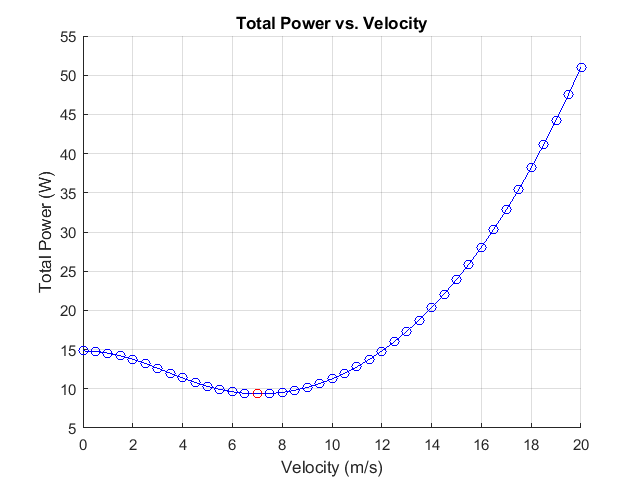

figure
hold on
plot(V, P_tot,'b-o')
plot(V(min_P_tot_idx), min_P_tot, 'r-o')
title('Total Power vs. Velocity')
xlabel('Velocity (m/s)')
ylabel('Total Power (W)')
grid on

% Range is maximized when (P_tot / V) is minimized
[min_P_tot_over_V, min_P_tot_over_V_idx] = min(P_tot ./ V);

t_for_max_range = (E_b * eta_m * eta_e) / P_tot(min_P_tot_over_V_idx);
max_range = t_for_max_range * V(min_P_tot_over_V_idx);

sprintf('The flight range is %.2f m', max_range)

ans = 'The flight range is 34061.49 m'

sprintf('The corresponding forward speed for max range is %.2f m/s', V(min_P_tot_over_V_idx))

ans = 'The corresponding forward speed for max range is 9.50 m/s'

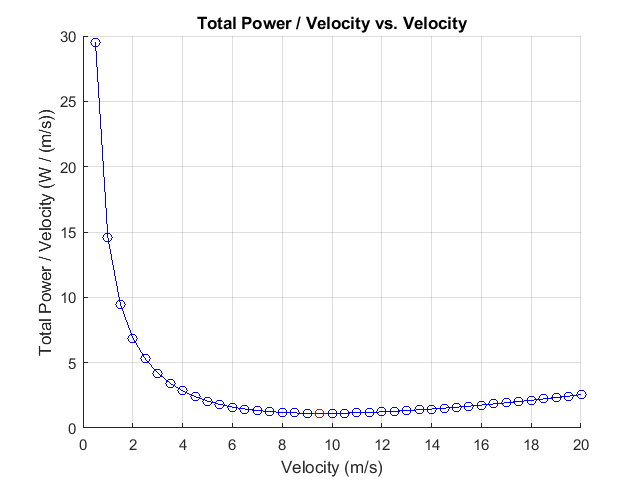

figure
hold on
plot(V, P_tot ./ V,'b-o')
plot(V(min_P_tot_over_V_idx), P_tot(min_P_tot_over_V_idx) ./ V(min_P_tot_over_V_idx), 'r-o')
title('Total Power / Velocity vs. Velocity')
xlabel('Velocity (m/s)')
ylabel('Total Power / Velocity (W / (m/s))')
grid on

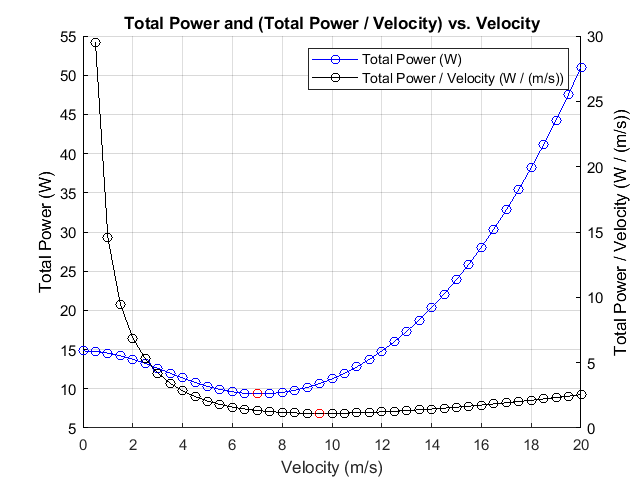

fig = figure;
set(fig,'defaultAxesColorOrder',[[0 0 0]; [0 0 0]]);
hold on

yyaxis left
plot(V, P_tot,'b-o')
plot(V(min_P_tot_idx), min_P_tot, 'r-o')
ylabel('Total Power (W)')

yyaxis right
plot(V, P_tot ./ V,'k-o')
plot(V(min_P_tot_over_V_idx), P_tot(min_P_tot_over_V_idx) ./ V(min_P_tot_over_V_idx), 'r-o')
ylabel('Total Power / Velocity (W / (m/s))')

title('Total Power and (Total Power / Velocity) vs. Velocity')
xlabel('Velocity (m/s)')
legend('Total Power (W)', '', 'Total Power / Velocity (W / (m/s))', '')
grid on